# ModelB SM Model

Model B to Single Machine Model, to model a weak grid with finite inertia. Based on Gomez's eqs 10.3-10.7 for both machines, grid is motoring, grid swing eq (5) may have additional damping term commented out. CURRENTLY NO DISTURBANCE/STEP-CHANGE, TBC.

### **Constants**

f  = 50;
ws = 2*pi*f;  %chosen reference rotational velocity, rad/s

% Machine 1 Network (Keep this part)
Xd1 = 0.1;
XT1 = 0.05;
X1 = Xd1 + XT1;

% Model B / Inverter Parameters (Replaces Machine 1 physics)
Pref_init  = 1.2;
Pref_after = 1.3;

H_equiv = 3;
J = 2*H_equiv / (ws^2);
Dp = 0.1;
nq = 0.05;
Kiq = 1;

% Base values for Machine 2 (Since we deleted D1 and H1)
D1_base = 0.1; 
H1_base = 3;

% Machine 2 / finite grid
D2 = 4*D1_base;
H2 = 4*H1_base;
Xd2 = 0.05;
XT2 = 0.05;
X2 = Xd2 + XT2;

% Network
XL = 0.3;
XTot = X1 + XL + X2;



### Design Parameters

% K1 = 1.2;  %Gen Gain Constant
% K2 = 4*K1; %Grid Gain Constant

### Specified Inputs

% Specified Inputs
K2 = 4*1.2;          % Grid Gain Constant
Pm2 = -Pref_init;         % Grid is initially motoring at equilibrium
V2o = 1;

%Comment out below to disable fault
V1o = 1;      
tstep = 5;
ramp_time = 0.01;

Pref_step = @(t) Pref_init + ...
    (Pref_after - Pref_init) * max(0,min((t-tstep)/ramp_time,1));

% % Check that a power-flow solution exists
% s1 = Pm*XL/(Vinf*V1o);
% s2 = Pm*XL/(Vinf*V1o_after);
% if abs(s1) > 1 && abs(s2) >1
%     error('No steady-state equilibrium exists for this Pm and V1o.');
% end

### Initial Conditions

% The following are for initial conditions at a steady state equilibrium
domega10 = 0;
domega20 = 0;
V1PCCmag0 = V1o;
V2PCCmag0 = V2o;
delta2PCC0 = 0;     
delta1PCC0 = asin(Pref_init*XL/(V1PCCmag0*V2PCCmag0));

Q12 = (V1PCCmag0^2 - V1PCCmag0*V2PCCmag0*cos(delta1PCC0-delta2PCC0))/XL;
Q21 = (V2PCCmag0^2 - V2PCCmag0*V1PCCmag0*cos(delta2PCC0-delta1PCC0))/XL;
Qref = Q12; % RPC Reference initialized to steady-state flosw

E10 = hypot(Pref_init*X1/V1PCCmag0, V1PCCmag0 + Q12*X1/V1PCCmag0);
delta10 = delta1PCC0 + atan2(Pref_init*X1/V1PCCmag0, V1PCCmag0 + Q12*X1/V1PCCmag0);
E20 = hypot(Pm2*X2/V2PCCmag0, V2PCCmag0 + Q21*X2/V2PCCmag0);
delta20 = delta2PCC0 + atan2(Pm2*X2/V2PCCmag0, V2PCCmag0 + Q21*X2/V2PCCmag0);

% State 3 is now the RPC Integrator state, initialized to steady state
x3_0 = E10 - V1o;

x0 = [delta10; domega10; x3_0; delta20; domega20; E20; V1PCCmag0; delta1PCC0; V2PCCmag0; delta2PCC0];

% Helper functions for local PCC power and dynamic E1
Ppcc = @(x) (x(7)*x(9)/XL)*sin(x(8)-x(10));
Qpcc = @(x) (x(7)^2 - x(7)*x(9)*cos(x(8)-x(10)))/XL;
E1 = @(x) V1o + nq*(Qref - Qpcc(x)) + x(3);

### State Space Equations and Solve

DynamicsEqs = @(t,x)[ x(2);                                                                               % 1: d(delta1)
                      (1/(J*ws))*(Pref_step(t) - Ppcc(x) - Dp*x(2));                                           % 2: APC Swing Eq
                      Kiq*(Qref - Qpcc(x));                                                               % 3: RPC Integrator
                      x(5);                                                                               % 4: d(delta2)
                      (ws/(2*H2))*(Pm2 + (E1(x)*x(6)/XTot)*sin(x(1)-x(4)) - D2*x(5));                   % 5: SM2 Swing Eq
                      K2*(V2o - x(9));                                                                    % 6: SM2 Voltage
                      (E1(x)*x(7)/X1)*sin(x(1)-x(8)) - Ppcc(x);                                        % 7: P balance PCC1
                      (E1(x)*x(7)*cos(x(1)-x(8)) - x(7)^2)/X1 - Qpcc(x);                                % 8: Q balance PCC1
                      (x(6)*x(9)/X2)*sin(x(4)-x(10)) - (x(9)*x(7)/XL)*sin(x(10)-x(8));                    % 9: P balance PCC2
                      (x(6)*x(9)*cos(x(4)-x(10)) - x(9)^2)/X2 - (x(9)^2 - x(9)*x(7)*cos(x(10)-x(8)))/XL]; % 10: Q balance PCC2

Mass = diag([1 1 1 1 1 1 0 0 0 0]);
options = odeset('Mass', Mass);
tspan = [0 30];
[t,x] = ode15s(DynamicsEqs, tspan, x0, options);

### Calculating PG and QG at each point in time

% Use x vector to get P, Q
delta1  = x(:,1);
domega1 = x(:,2);
x3      = x(:,3);
delta2  = x(:,4);
domega2 = x(:,5);
E2      = x(:,6);
V1PCCmag  = x(:,7);
delta1PCC = x(:,8);
V2PCCmag  = x(:,9);
delta2PCC = x(:,10);

PG      = zeros(length(t),1);
QG      = zeros(length(t),1);

for n = 1:length(t)
    
    PG(n) = (V1PCCmag(n)*V2PCCmag(n)/XL)*sin(delta1PCC(n)-delta2PCC(n)); % Active power from PCC1 to PCC2

    QG(n) = (V1PCCmag(n)^2/XL) - (V1PCCmag(n)*V2PCCmag(n)/XL)*cos(delta1PCC(n)-delta2PCC(n)); %Reactive power from PCC1 to PCC2
end

### Plot -WHICH PLOTS WE WANT TBC

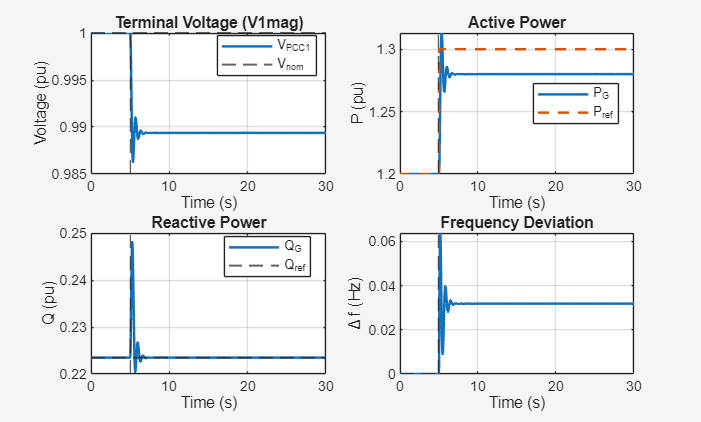

%% Plot Results

% Generate Pref command over simulation time
Pref_plot = Pref_step(t);

figure('Visible','on');

%% 1. Terminal Voltage
subplot(2,2,1);

plot(t, V1PCCmag, 'LineWidth', 1.5);
hold on;
yline(V1o, '--', 'LineWidth', 1.2);
xline(tstep, '--');

xlabel('Time (s)');
ylabel('Voltage (pu)');
legend('V_{PCC1}', 'V_{nom}', 'Location', 'best');
title('Terminal Voltage (V1mag)');
grid on;


%% 2. Active Power
subplot(2,2,2);

plot(t, PG, 'LineWidth', 1.5);
hold on;
plot(t, Pref_plot, '--', 'LineWidth', 1.5);
xline(tstep, '--');

xlabel('Time (s)');
ylabel('P (pu)');
legend('P_G', 'P_{ref}', 'Location', 'best');
title('Active Power');
grid on;


%% 3. Reactive Power
subplot(2,2,3);

plot(t, QG, 'LineWidth', 1.5);
hold on;
yline(Qref, '--', 'LineWidth', 1.2);
xline(tstep, '--');

xlabel('Time (s)');
ylabel('Q (pu)');
legend('Q_G', 'Q_{ref}', 'Location', 'best');
title('Reactive Power');
grid on;


%% 4. Frequency Deviation
subplot(2,2,4);

plot(t, domega1/(2*pi), 'LineWidth', 1.5);
hold on;
yline(0, '--');
xline(tstep, '--');

xlabel('Time (s)');
ylabel('\Delta f (Hz)');
title('Frequency Deviation');
grid on;